% clear variables in workspace and close all figures
clearvars; close all;

% reading the data
% data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');
data = readtimetable('../Datasets/Ontario/OntarioIESO.xlsx');

TR = timerange('2010-01-01','2019-12-31 23:00:00', "closed");
data = data(TR, :);   % new total dataset

% detecting and removing outliers using Hampel filter
data.DemandMW = hampel(data.DemandMW);
data.Temperature = hampel(data.Temperature);
data.Humidity = hampel(data.Humidity);
data.Dewpoint = hampel(data.Dewpoint);
data.WindDirection = hampel(data.WindDirection);
data.WindSpeed = hampel(data.WindSpeed);

% Normalizing the variables

% y = (x - min) / (max - min)
tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

clearvars -except data ndata mindp maxdp

% TR = timerange('2010-01-01','2019-01-01');  % All of 2010 - 2018
% trainvald = ndata(TR, :);   % training data
% 
% TR = timerange('2019-01-01','2020-01-01');  % All of 2019
% testd = ndata(TR, :);   % testing data

## The Regression Model

### Inputs and Target Creation

InputsTarget = InputsCreation(ndata);   % returns the input and the target. The last column is the target variable

TR = timerange('2010-01-08','2019-01-01');  % All of 2010 - 2018
traind = InputsTarget(TR, :);   % training data

TR = timerange('2019-01-01','2020-01-01');  % All of 2019
testd = InputsTarget(TR, :);   % testing data
clear TR

% conversion to array
train_it = traind;     % training data input and target
train_it = timetable2table(train_it);
train_it = table2array(train_it(:, 2:end));

test_it = testd;     % testing data input and target
test_it = timetable2table(test_it);
test_it = table2array(test_it(:, 2:end));  

### Training the Model

Mdl_LR = trainRegressionModel(train_it);   % trains the model using the inputs and target

## Predict the test dataset

yReg = Mdl_LR.predictFcn(test_it(:, 1:end-1));  % returns the predicted values

% Denormalization
actuals = testd.Target_DemandMW * (maxdp(1) - mindp(1)) + mindp(1);
yReg = yReg * (maxdp(1) - mindp(1)) + mindp(1);

### Calculate errors

[Metrics, errors, AEs, APEs, MAPE] = ErrorMetrics(actuals, yReg);

Metrics

Metrics = 5×2 table
                   Metrics                       Var2   
    ______________________________________    __________

    {'MAPE - Mean Absolute Percent Error'}         3.635
    {'ME - Mean Error'                   }       -49.669
    {'MAE - Mean Absolute Error'         }        560.43
    {'MSE - Mean Squared Error'          }    5.3772e+05
    {'RMSE - Root Mean Squared Error'    }        733.29


### Plots of the Test dataset

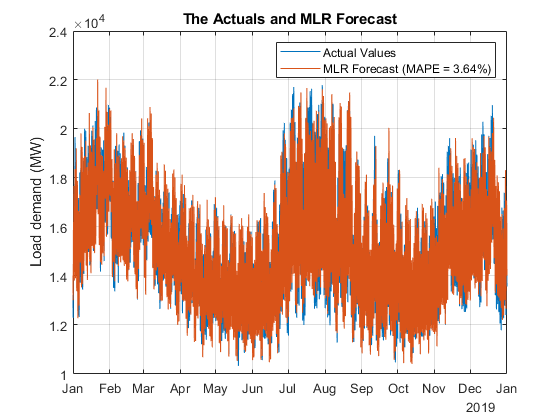

figure;

% plot actual values
plot(testd.DateTime, actuals, 'DisplayName','Actual Values')
title('The Actuals and MLR Forecast')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot arima forecast
DisplayName = num2str(MAPE, 'MLR Forecast (MAPE = %.2f%%)');
plot(testd.DateTime,yReg, 'DisplayName', DisplayName)
legend('show')

## Performance Analysis of the Algorithm

dt = testd.DateTime;    % DateTime of the test dataset

figure;
time24 = dt.Hour + 1; % Time = 1...24 hrs
[dnum, dname] = weekday(dt, 'long');
labeld = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};
labelm = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug',...
          'Sep', 'Oct', 'Nov', 'Dec'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


### Box plots of the error distribution

% Hourly
sp(1) = nexttile;
boxplot(errors, time24)
title('Hourly Horizon')

% Daily
xtick = [7,1,2,3,4,5,6];    % the position we want them displayed as, i.e Mon - Sun
sp(2) = nexttile;
boxplot(errors, dnum,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('Daily Horizon')

% Monthly
sp(3) = nexttile;
boxplot(errors, dt.Month, 'Labels', labelm)
title('Monthly Horizon')

linkaxes(sp, 'y')
clear sp


### Absolute Errors plots 

% Absolute Errors plots    
AE = AEs/100;   % divided by 100, so I can fit multiple charts

% Hourly
sp(1) = nexttile;
stats = grpstats(AE, dt.Hour, "mean");
plot(stats, '-o')
grid
hold on

% Daily
sp(2) = nexttile;
stats = grpstats(AE, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labeld)
grid
hold on

% Monthly
sp(3) = nexttile;
stats = grpstats(AE, dt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


### Absolute Percent Errors plot

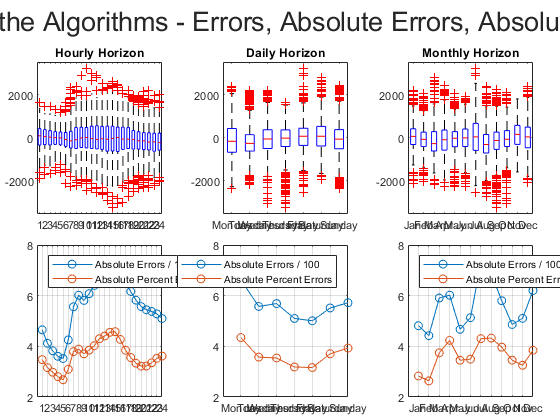

% Hourly
sp(1) = nexttile(4);
stats = grpstats(APEs, dt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Errors / 100','Absolute Percent Errors', 'Location','northwest')
grid on

sp(2) = nexttile(5);
stats = grpstats(APEs, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Errors / 100','Absolute Percent Errors', 'Location','northeast')
grid on

sp(3) = nexttile(6);
stats = grpstats(APEs, dt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
legend('Absolute Errors / 100','Absolute Percent Errors', 'Location','northwest')
grid on
linkaxes(sp, 'y')